% Jep Brinkmann Thesis HMM example
clc; close all;

k = 5;
options.method = "random";
options.epsilon = 1/10;

T_seq = 1e7;
d_range = [10, 30, 50, 100, 200];


s = 100;

all_convergences = zeros(length(d_range), s);


for i = progress(1:length(d_range))
    
    d = d_range(i);
    [T, O, pi, k, d] = generateHMM(k, d, 1, options);
   
    
    U{1} = Stochasticize(O * diag(pi) * T' / diag(T * pi'));
    U{2} = O;
    U{3} = Stochasticize(O * T);
    
    P3 = permute(cpdgen(U)./sum(cpdgen(U), "all"), [1, 2, 3]);
    
    [seq, states] = generate_hmm_sequence(T, O, pi, T_seq);
    
    [P3_n, T_seq_Error] = estimate_joint_prob(seq, d, P3);
    norm(P3 - P3_n, "fro");
    
    all_convergences(i, :) = T_seq_Error;
end

Processing:  000%  |                                          | 0/5it [00:00:00<Inf:NaN:NaN, Inf it/s]


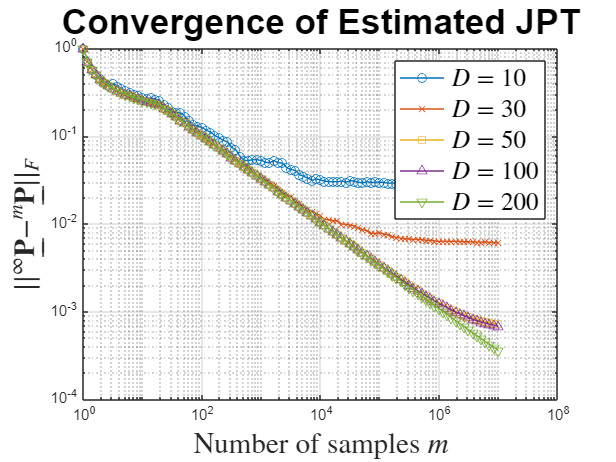


figure()
t = logspace(0, log10(T_seq), s-1);
loglog(t, all_convergences(1, 1:end-1), '-o', t, all_convergences(2, 1:end-1), '-x', t, all_convergences(3, 1:end-1), '-square', t, all_convergences(4, 1:end-1), '-^', t, all_convergences(5, 1:end-1), '-v')
title("Convergence of Estimated JPT", "FontSize", 24)
ylabel("$||^\infty\underline{\mathbf{P}} - ^m\underline{\mathbf{P}}||_F$", "Interpreter","latex", "FontSize", 20, "FontWeight","bold")
xlabel("Number of samples $m$", "Interpreter","latex", "FontSize", 20, "FontWeight","bold")
legendLabels = arrayfun(@(i) sprintf('$D = %d$', i), d_range, 'UniformOutput', false);
legend(legendLabels, 'Interpreter', 'latex', "FontSize", 17);
% xlim([1, T_seq])
% ylim([min(all_convergences(:, end)), 1])
grid on


k=4;
d=30;
n=5;
m = 1e6;

hmm_options.epsilon = 1/10;
hmm_options.method = "random";
hmm_options.distribution = 'Normal';

[T, O, pi, k, d] = generateHMM(k, d, n, hmm_options);
[seq, states] = generate_multivariate_hmm_sequence(T, O, pi, m);


P3 = cell(n, 1);
P3_n = cell(n, 1);

for i = 1:n
    U{1} = Stochasticize(O{i} * diag(pi) * T' / inv(diag(T * pi')));
    U{2} = O{i};
    U{3} = Stochasticize(O{i} * T);
    
    P3{i} = permute(cpdgen(U)/sum(cpdgen(U), "all"), [1, 2, 3]);

    P3_n{i} = ProbabilityTensorGenerate(seq(i, :), 3, d);
end



alpha = 1e-6;

rho = 0.95;
epsilon = 1e-6;
nIter = 10;

P3_em = cell(n, 1);
P3_mle = cell(n, 1);

for i = 1:n
    P3_em{i} = EM_JPT_estimation(seq(i, :), d, rho, epsilon, nIter);
    P3_mle{i} = laplacian_smoothing_mle(P3_n{i}, alpha);

    % norm(P3{i} - P3_n{i}, "fro")
    % norm(P3{i} - P3_em{i}, "fro")
    % norm(P3{i}- P3_mle{i}, "fro")
end




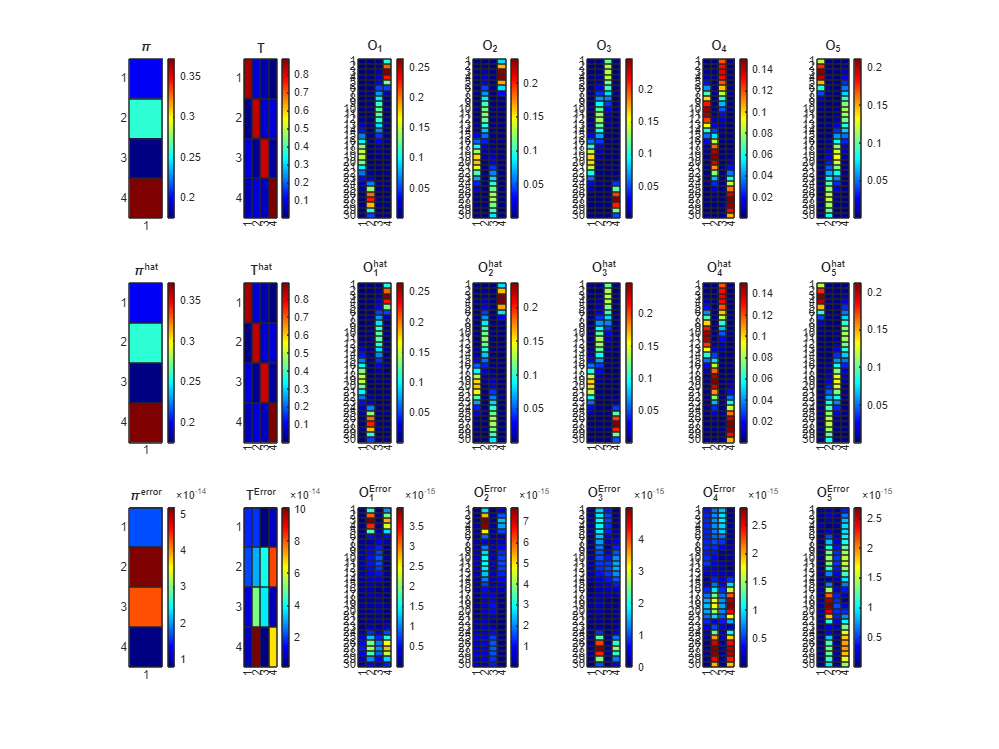

ans = 1.1760e-13

alpha = 0.1;
rho = 0.85;

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-14;
cpd_options.th_relerr = 1e-7;
cpd_options.epsilon = 1/10; 

[T_hat, O_hats, pi_hat, output] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, cpd_options);
[T_hat, O_hats, pi_hat] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);

HMMError(T, O, T_hat, O_hats, true)

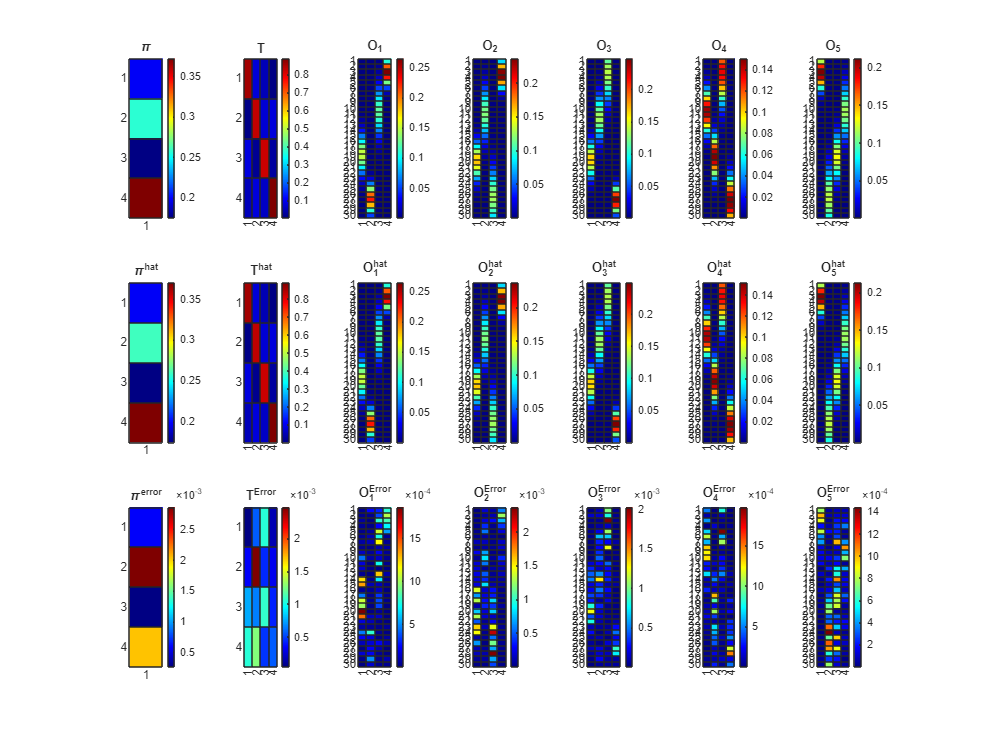

ans = 0.0094



[T_hat, O_hats, pi_hat, output] = multivariate_coupled_cpd_2(P3_n, k, d, n, alpha, rho, cpd_options);
[T_hat, O_hats, pi_hat] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);

HMMError(T, O, T_hat, O_hats, true)

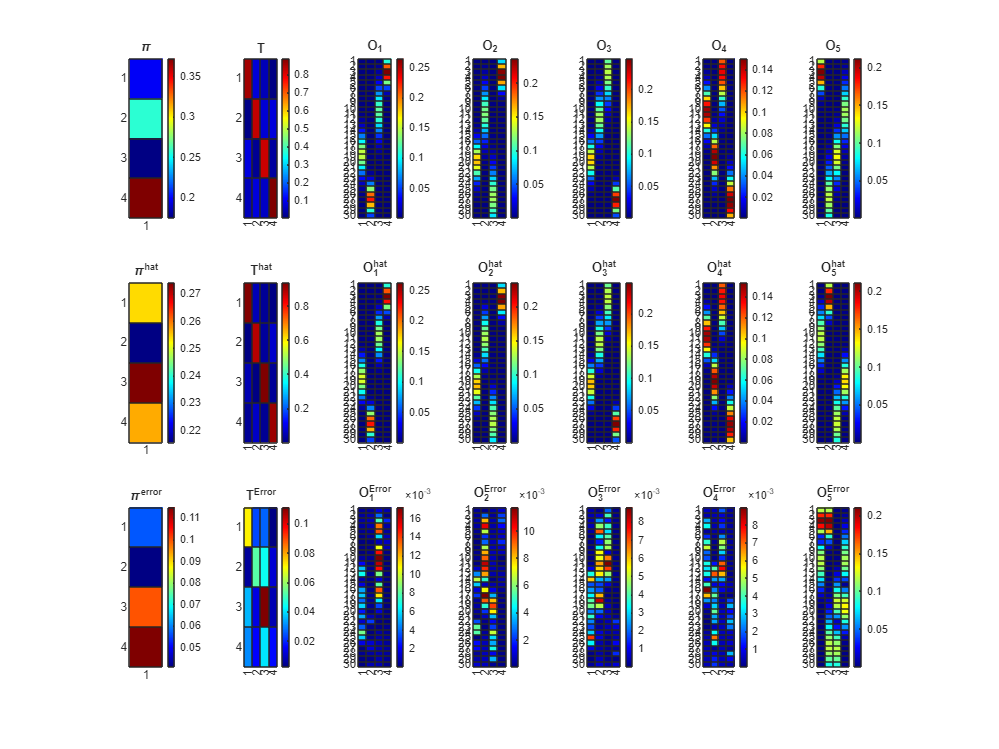

ans = 0.4049


[T_hat, O_hats, pi_hat, output] = multivariate_coupled_cpd_2(P3_em, k, d, n, alpha, rho, cpd_options);
[T_hat, O_hats, pi_hat] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);
HMMError(T, O, T_hat, O_hats, true)

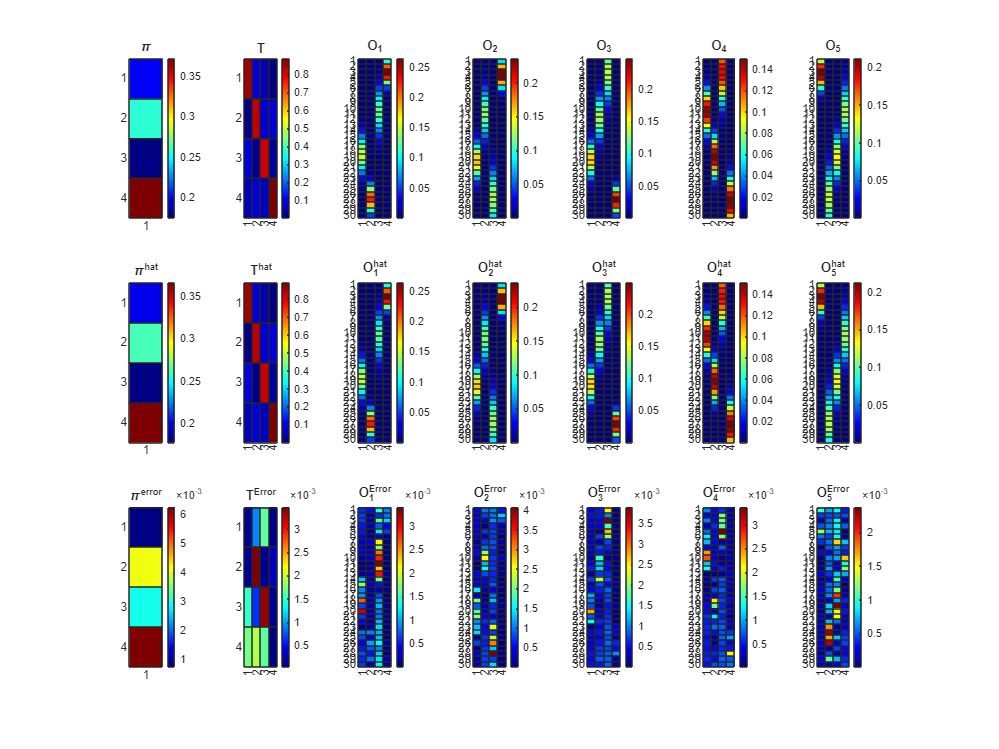

ans = 0.0172


[T_hat, O_hats, pi_hat, output] = multivariate_coupled_cpd_2(P3_mle, k, d, n, alpha, rho, cpd_options);
[T_hat, O_hats, pi_hat] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);
HMMError(T, O, T_hat, O_hats, true)




% TripleTensorBubblePlot(reshape(P3, numel(P3), []), reshape(M, numel(M), []), d)



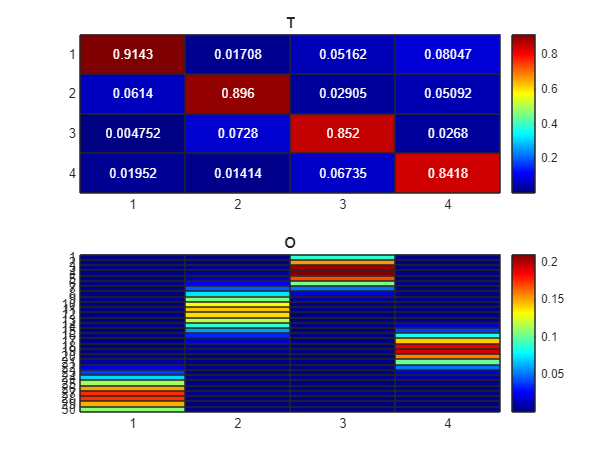

k = 4;
d = 30;
m = 1e6;

options.method = "random";
options.epsilon = 1/10;

options.maxIter = 2500;
options.tol = 1e-16;

[T, O, pi, k, d] = generateHMM(k, d, 1, options);

figure()
subplot(2, 1, 1)
h = heatmap(T, Colormap=jet());
h.Title = 'T';
subplot(2,1,2)
h = heatmap(O, Colormap=jet());
h.Title = 'O';

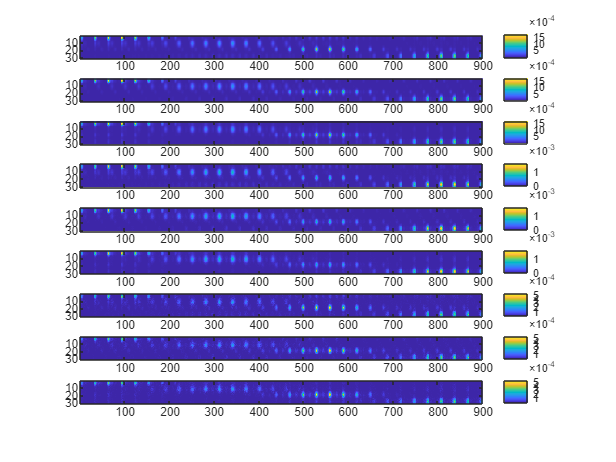


[seq, states] = generate_hmm_sequence(T, O, pi, m);




U{1} = Stochasticize(O * diag(pi) * T' / inv(diag(T * pi')));
U{2} = O;
U{3} = Stochasticize(O * T);

P_true = cpdgen(U)/k;

P_est = ProbabilityTensorGenerate(seq, 3, d);

P1_est = mode_n_matricization(P_est, 1);
P2_est = mode_n_matricization(P_est, 2);
P3_est = mode_n_matricization(P_est, 3);

P1_true = mode_n_matricization(P_true, 1);
P2_true = mode_n_matricization(P_true, 2);
P3_true = mode_n_matricization(P_true, 3);

figure()

colormap parula
colorbar

subplot(9, 1, 1)
imagesc(P1_true);
colorbar

subplot(9, 1, 2)
imagesc(P2_true);
colorbar

subplot(9, 1, 3)
imagesc(P3_true);
colorbar

subplot(9, 1, 4)
imagesc(P1_est);
colorbar

subplot(9, 1, 5)
imagesc(P2_est);
colorbar

subplot(9, 1, 6)
imagesc(P3_est);
colorbar

subplot(9, 1, 7)
imagesc(abs(P1_true - P1_est));
colorbar

subplot(9, 1, 8)
imagesc(abs(P2_true - P2_est));
colorbar

subplot(9, 1, 9)
imagesc(abs(P3_true - P3_est));
colorbar